# Optimisation: Coursework

Student name: Li, Hongyi            CID: 01945466              Email: [hongyi.li20@imperial.ac.uk](mailto:hongyi.li20@imperial.ac.uk)

## PART I

#### A1) Compute analytically all stationary points of the function v(x, y) and verify if they are minimizers/maximizers/saddle points.

The stationary point of the Rosenbrock function can be computed by solving

$$$
\nabla v=\left[ \begin{array}{c}
	2x-400x\left( y-x^2 \right) -2\\
	200\left( y-x^2 \right)\\
\end{array} \right] =0
$$
$，

yielding the stationary point $x^\star=1, y^\star=1$.

Since $$$
\nabla ^2v\left( x^\star, y^\star\right) =\left[ \begin{array}{cc}
	802&		-400\\
	-400&		200\\
\end{array} \right] \geq 0
$$
$, $(x^\star, y^\star)$ is a local minimizer.

Verify the above result with MATLAB:

Define the function v(x,y)

clear;
clc;
syms x y;
v=100*(y-x^2)^2+(1-x)^2

$$v = {\left(x-1\right)}^{2}+100\,{\left(y-x^{2}\right)}^{2}$$

Claculate the derivatives

dx= diff(v,x)

$$dx = 2\,x-400\,x\,\left(y-x^{2}\right)-2$$

dy= diff(v,y)

$$dy = 200\,y-200\,x^{2}$$

Solving for the stationary points

sta_point=solve([dx==0,dy==0],[x,y]);
fprintf('The stationary point of v is (%.2f,%.2f)',sta_point.x,sta_point.y)

The stationary point of v is (1.00,1.00)

Second order derivatives

dxdx= diff(dx,x)

$$dxdx = 1200\,x^{2}-400\,y+2$$

dxdy= diff(dx,y)

$$dxdy = -400\,x$$

dydx= diff(dy,x)

$$dydx = -400\,x$$

dydy= diff(dy,y)

$$dydy = 200$$

dd=[subs(dxdx,[x,y],[1,1]),subs(dxdy,[x,y],[1,1]);subs(dydx,[x,y],[1,1]),subs(dydy,[x,y],[1,1])]

$$dd = \left(\begin{array}{cc} 802 & -400\\ -400 & 200 \end{array}\right)$$

Calculate the eigenvalues of $\nabla ^2v$

all(eig(dd)>0)

ans = logical
   1


Thus, $\nabla ^2v$ is positive definite, implying that $(x^\star, y^\star)$ is a local minimizer.

#### A2) Plot (using Matlab or a similar SW) the level sets of the function v(x, y).

clear;
clc;

Creating a meshgrid for the plotting counter lines

[x,y]=meshgrid([-2:0.001:2],[-1:0.001:3]);
v=100.*(y-x.^2).^2+(1-x).^2;

Plot 100 level sets

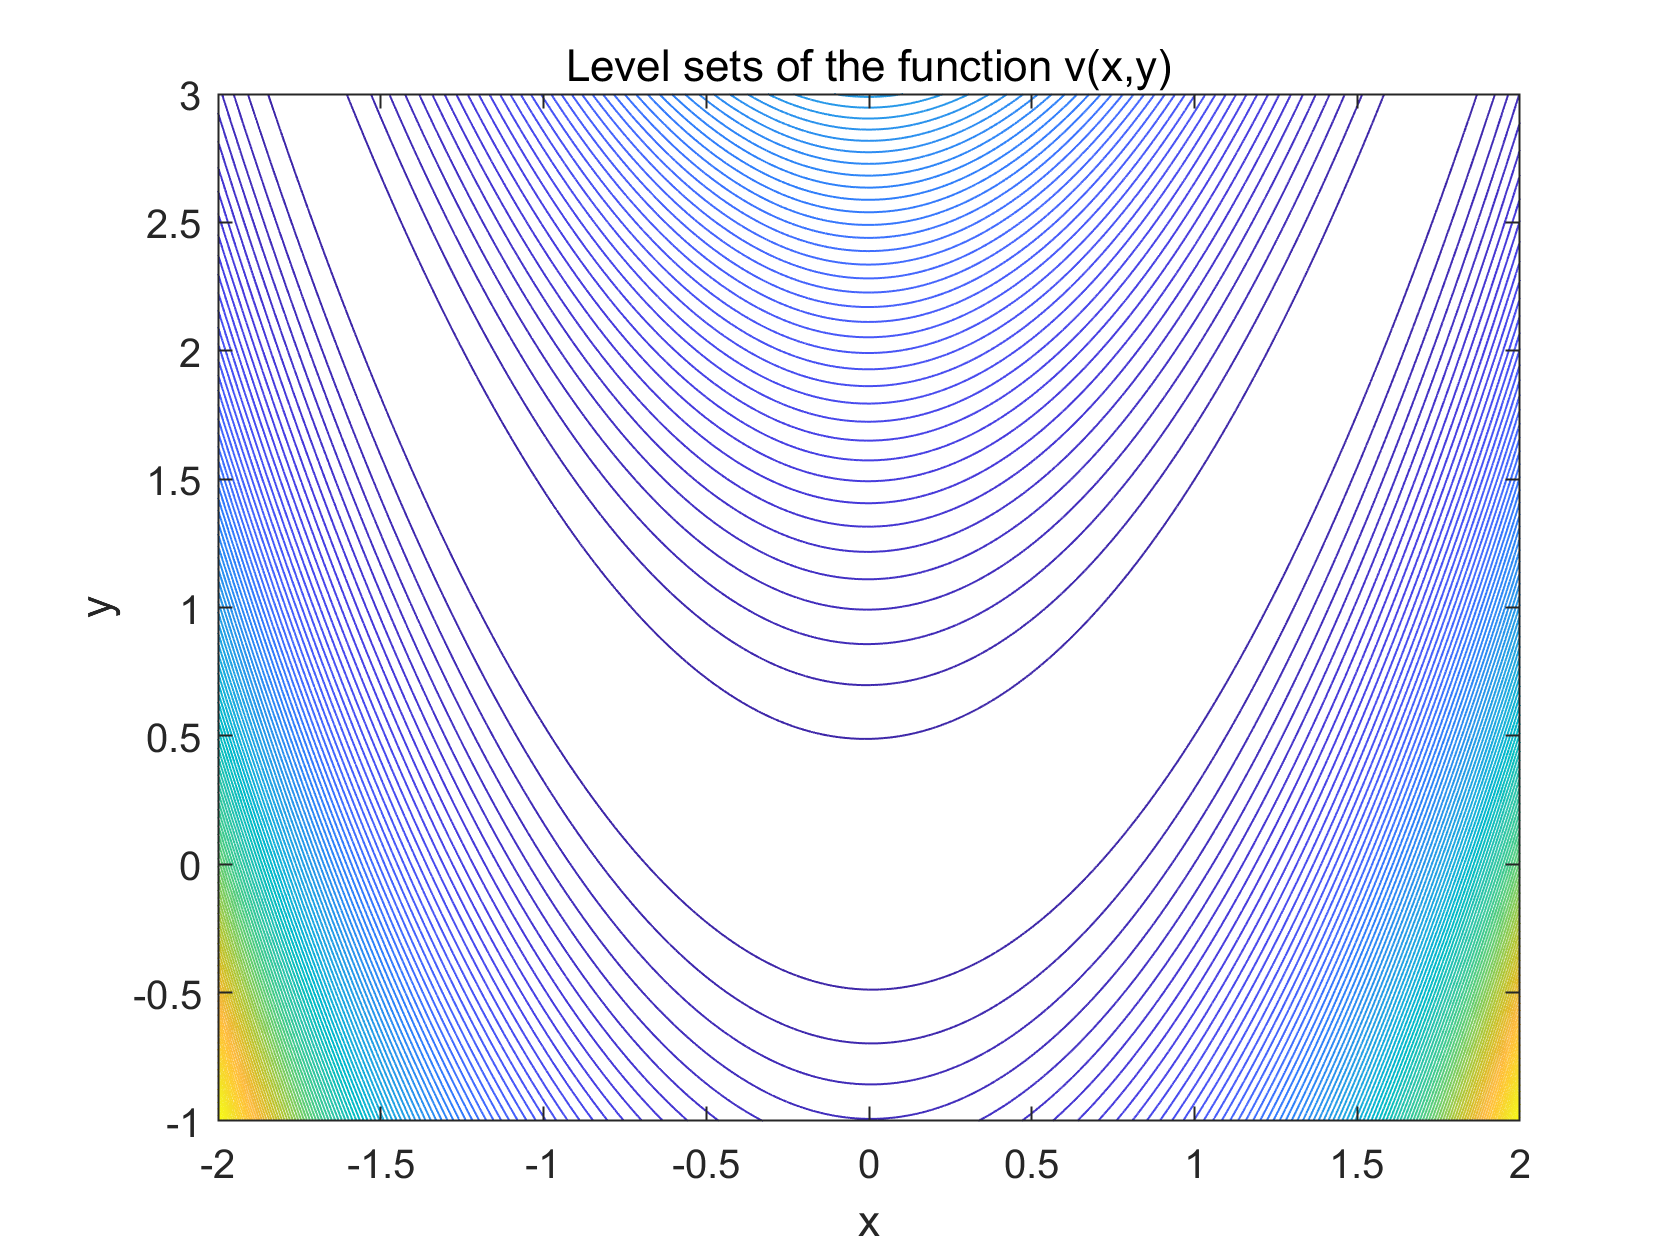

contour(x,y,v,100)
xlabel('x')
ylabel('y')
title('Level sets of the function v(x,y)')

#### A3) Implement procedures for the minimization of the function v(x, y) using the gradient method with Armijo line search.

For convenience, in the following codes, the function $v(x, y)$ and its derivatives (both first order and second order) are pre-defined as MATLAB functions, which can be found in the appendix.

clear;
clc;

The initial point suggested in A8a) is used for the testing of the algorithms in A3)~A7)

%initial guess
X(1)=-3/4;
Y(1)=1;

Here, the research direction is selected as the direction of anti-gradient.

%initial decent direction
Jacobian=[dx(X(1),Y(1));dy(X(1),Y(1))];
d=-Jacobian;

In the gradient method, the stoping criterion is 

$$$
\nabla v =0
$$
$.

Here, it is modified as checking whether the derivative is smaller than a sufficiently small positive value.

When applying armijo line search, the algorithm should find the largest $\alpha$ that satisfies

$$$
\phi \left( \alpha \right) =v\left( (x_k, y_k)+\alpha d_k \right) -v\left( x_k, y_k \right) =\gamma \alpha \nabla v\left( x_k ,y_k \right) \prime d_k
$$
$,

where $\alpha = a\sigma^j, j=0,1,...$ .

%stoping criteria
e=1e-8;
%counter
i=1;
%gradient method
while norm(Jacobian)>e
    %armijo method
    delta=0.5;
    gamma=1/3;
    j=1;
    alpha=1;
    while j>0
        x_next=X(i)+alpha*d(1);
        y_next=Y(i)+alpha*d(2);
        if v(x_next,y_next)-v(X(i),Y(i))<=gamma*alpha*Jacobian.'*d
            j=0;
            alpha_armijo=alpha;
        else
            alpha=alpha*delta;
        end
    end
    %calculate next iterate
    X(i+1)=X(i)+alpha_armijo*d(1);
    Y(i+1)=Y(i)+alpha_armijo*d(2);
    %update
    i = i+1;
    Jacobian=[dx(X(i),Y(i)),dy(X(i),Y(i))];
    d=-Jacobian;
end

The result of the gradient method with armijo line search is

fprintf('X_star=%.2f, Y_star=%.2f.',X(i),Y(i))

X_star=1.00, Y_star=1.00.

fprintf('Getting the above result in %i interations',i)

Getting the above result in 1475 interations

which consist with the stationary point calculated analytically in A1), implying the effectiveness of the algorithm.

As stated in A8, the cost is defined as

$$$
J_k=\log \left( \left( x_k-1 \right) ^2+\left( y_k-1 \right) ^2 \right) 
$$
$.

%cost calculation
J=cost(X,Y);

The result is saved for plotting in A8.

save('Gradient with armijo');

#### A4a) Implement procedures for the minimization of the function v(x, y) using Newton method without Armijo line search.

Using the same initial point and stoping criteria

clear;
clc;
%initial guess
X(1)=-3/4;
Y(1)=1;
%stoping criteria
e=1e-8;
%counter
i=1;
%the derivatives at the initial point
Jacobian=[dx(X(1),Y(1));dy(X(1),Y(1))];
JJ=[dxdx(X(1),Y(1)),dxdy(X(1),Y(1));dydx(X(1),Y(1)),dydy(X(1),Y(1))];

In Newtow's method, the decent direction is selected by minimizing the quadratic approximation $q(d)$ of the objective function.

$$$
q\left( d \right) =v\left( x_k,y_k \right) +\nabla v\left( x_k,y_k \right) \prime d+\frac{1}{2}d\prime\nabla ^2v\left( x_k,y_k \right) d
$$
$,

yielding

$$$
d=-\left[ \nabla ^2v\left( x_k,y_k \right) \right] ^{-1}\nabla v\left( x_k,y_k \right) 
$$
$.

while norm(Jacobian)>e
    %decent direction
    d=-inv(JJ)*Jacobian;
    %next iterate
    X(i+1)=X(i)+d(1);
    Y(i+1)=Y(i)+d(2);
    %update
    i=i+1;
    Jacobian=[dx(X(i),Y(i));dy(X(i),Y(i))];
    JJ=[dxdx(X(i),Y(i)),dxdy(X(i),Y(i));dydx(X(i),Y(i)),dydy(X(i),Y(i))];
end

The result of the Newton method without armijo line search is

fprintf('X_star=%.2f, Y_star=%.2f.',X(i),Y(i))

X_star=1.00, Y_star=1.00.

fprintf('Getting the above result in %i interations.',i)

Getting the above result in 7 interations.

which consist with the stationary point calculated analytically in A1), implying the effectiveness of the algorithm.

The calculation of the cost function and saving the result.

%cost calculation
J=cost(X,Y);
save('Newton without armijo');

#### A4b) Implement procedures for the minimization of the function v(x, y) using Newton method with Armijo line search.

Using the same initial point and stoping criteria

clear;
clc;
%initial guess
X(1)=-3/4;
Y(1)=1;
%stoping criteria
e=1e-8;
%counter
i=1;
%initial decent direction
Jacobian=[dx(X(1),Y(1)),dy(X(1),Y(1))];
JJ=[dxdx(X(1),Y(1)),dxdy(X(1),Y(1));dydx(X(1),Y(1)),dydy(X(1),Y(1))];

The armijo line search method is also similar to the one implemented in A3).

while norm(Jacobian)>e
    %decent direction
    d=-inv(JJ)*Jacobian.';
    delta=0.5;
    gamma=1/3;
    j=1;
    alpha=1;
    while j>0
        x_next=X(i)+alpha*d(1);
        y_next=Y(i)+alpha*d(2);
        if v(x_next,y_next)-v(X(i),Y(i))<=gamma*alpha*Jacobian*d
            j=0;
            alpha_armijo=alpha;
        else
            alpha=alpha*delta;
        end
    end
    %next iterate
    X(i+1)=X(i)+alpha_armijo*d(1);
    Y(i+1)=Y(i)+alpha_armijo*d(2);
    %update
    i=i+1;
    Jacobian=[dx(X(i),Y(i)),dy(X(i),Y(i))];
    JJ=[dxdx(X(i),Y(i)),dxdy(X(i),Y(i));dydx(X(i),Y(i)),dydy(X(i),Y(i))];
end

The result of the Newton method with armijo line search is

fprintf('X_star=%.2f, Y_star=%.2f.',X(i),Y(i))

X_star=1.00, Y_star=1.00.

fprintf('Getting the above result in %i interations.',i)

Getting the above result in 20 interations.

which consist with the stationary point calculated analytically in A1), implying the effectiveness of the algorithm.

The calculation of the cost function and saving the result.

%cost calculation
J=cost(X,Y);
save('Newton with armijo');

#### A5) Implement procedures for the minimization of the function v(x, y) using the Polak-Ribiere algorithm with Armijo line search.

Using the same parameters

clear;
clc;
%initial guess
X(1)=-3/4;
Y(1)=1;
%stoping criteria
e=1e-8;
%counter
i=1;
%initial decent direction
Jacobian=[dx(X(1),Y(1));dy(X(1),Y(1))];
d=-Jacobian;
%armijo method parameters
delta=0.5;
gamma=1/3;

The Polak-Ribiere algorithm updates the decent direction using the following equation

$$$
d_k=-\nabla v\left( x_k,y_k \right) +\frac{\nabla v\left( x_k,y_k \right) \prime\left[ \nabla v\left( x_k,y_k \right) -\nabla v\left( x_{k-1},y_{k-1} \right) \right]}{\left\| \nabla v\left( x_{k-1},y_{k-1} \right) \right\| ^2}d_{k-1} , k \geq 1
$$
$.

In some documents, it is suggested to reset the decent direction periodically, i.e. set $d_k=-\nabla v\left( x_k,y_k \right)$ every n iterations. This trick, also known as the "restart" of the conjugate directions methods, will help to restore the conjugacy of directions for non-quadratic problems during the process. However, it is not necessary in this question (requires 2377 iterations for n=100 instead of 1890 iterations to get to the stationary point). 

while norm(Jacobian)>e
    %armijo method
    j=1;
    alpha=1;
    while j>0
        x_next=X(i)+alpha*d(1);
        y_next=Y(i)+alpha*d(2);
        if v(x_next,y_next)-v(X(i),Y(i))<=gamma*alpha*Jacobian.'*d
            j=0;
            alpha_armijo=alpha;
        else
            alpha=alpha*delta;
        end
    end
    %next iterate
    X(i+1)=X(i)+alpha_armijo*d(1);
    Y(i+1)=Y(i)+alpha_armijo*d(2);
    %update
    i=i+1;
    J_old=Jacobian;
    d_old=d;
    Jacobian=[dx(X(i),Y(i));dy(X(i),Y(i))];
    d=-Jacobian+(Jacobian'*(Jacobian-J_old)/norm(J_old)^2)*d_old;
end

The result of the Polak-Ribiere algorithm with Armijo line search is

fprintf('X_star=%.2f, Y_star=%.2f.',X(i),Y(i))

X_star=1.00, Y_star=1.00.

fprintf('Getting the above result in %i interations.',i)

Getting the above result in 54 interations.

which consist with the stationary point calculated analytically in A1), implying the effectiveness of the algorithm.

The calculation of the cost function and saving the result.

%cost calculation
J=cost(X,Y);
save('Polak-Ribiere');

#### A6) Implement procedures for the minimization of the function v(x, y) using the Broyden-Fletcher-Goldfarb-Shanno algorithm with Armijo line search.

Using the same parameters

clear;
clc;
%initial guess
X(1)=-3/4;
Y(1)=1;
%stoping criteria
e=1e-8;
%counter
i=1;
%initial decent direction
Jacobian=[dx(X(1),Y(1));dy(X(1),Y(1))];
H=eye(2);
d=-H*Jacobian;
%armijo method parameters
delta=0.5;
gamma=1/3;

In the Quasi-Newton methods, the next iterative is calculated as

$$$
\left[ \begin{array}{c}
	x_{k+1}\\
	y_{k+1}\\
\end{array} \right] =\left[ \begin{array}{c}
	x_k\\
	y_k\\
\end{array} \right] -\alpha _kH_k\nabla v\left( x_k,y_k \right) 
$$
$,

yielding the decent direction

$$$
d_k=-H_k\nabla v\left( x_k,y_k \right) 
$$
$.

Setting $$$
\gamma _k=\nabla v\left( x_{k+1},y_{k+1} \right) -\nabla v\left( x_k,y_k \right) 
$$
$ and $$$
\delta _k=\left[ \begin{array}{c}
	x_{k+1}\\
	y_{k+1}\\
\end{array} \right] -\left[ \begin{array}{c}
	x_k\\
	y_k\\
\end{array} \right] 
$$
$, the Broyden-Fletcher-Goldfarb-Shanno formula of $H_k$ is defined by the equations

$$$
H_k=\begin{cases}
	H_0=I\\
	H_{k+1}=H_k+\frac{\delta _k\delta _k\prime}{\delta _k\prime\gamma _k}-\frac{H_k\gamma _k\gamma _k\prime H_k}{\gamma _k\prime H_k\gamma _k}+v_kv_k\prime\\
\end{cases}
$$
$ ,

where

$$$
v_k=\left( \gamma _k\prime H_k\gamma _k \right) ^{\frac{1}{2}}\left( \frac{\delta _k}{\delta _k\prime\gamma _k}-\frac{H_k\gamma _k}{\gamma _k\prime H_k\gamma _k} \right) 
$$
$.

while norm(Jacobian)>e
    %armijo method
    j=1;
    alpha=1;
    while j>0
        x_next=X(i)+alpha*d(1);
        y_next=Y(i)+alpha*d(2);
        if v(x_next,y_next)-v(X(i),Y(i))<=gamma*alpha*Jacobian'*d
            j=0;
            alpha_armijo=alpha;
        else
            alpha=alpha*delta;
        end
    end
    %next iterate
    X(i+1)=X(i)+alpha_armijo*d(1);
    Y(i+1)=Y(i)+alpha_armijo*d(2);
    %update
    i=i+1;
    J_old=Jacobian;
    d_old=d;
    H_old=H;
    Jacobian=[dx(X(i),Y(i));dy(X(i),Y(i))];
    GAMMA=Jacobian-J_old;
    DELTA=[X(i);Y(i)]-[X(i-1);Y(i-1)];
    V=(GAMMA'*H_old*GAMMA)^0.5*((DELTA/(DELTA'*GAMMA))-(H_old*GAMMA)/(GAMMA'*H_old*GAMMA));
    H=H_old+DELTA*DELTA'/(DELTA'*GAMMA)-(H_old*(GAMMA*GAMMA')*H_old)/(GAMMA'*H_old*GAMMA)+V*V';
    d=-H*Jacobian;
end

The result of the Broyden-Fletcher-Goldfarb-Shanno algorithm with Armijo line search is

fprintf('X_star=%.2f, Y_star=%.2f.',X(i),Y(i))

X_star=1.00, Y_star=1.00.

fprintf('Getting the above result in %i interations.',i)

Getting the above result in 36 interations.

which consist with the stationary point calculated analytically in A1), implying the effectiveness of the algorithm.

The calculation of the cost function and saving the result.

%cost calculation
J=cost(X,Y);
save('Broyden-Fletcher-Goldfarb-Shanno');

#### A7) Implement procedures for the minimization of the function v(x, y) using the simplex method. Consider modifying the method to improve convergence properties of the algorithm.

Using the same parameters

clear;
clc;
%stoping criteria
e=1e-12;
%counter
i=0;
%initial guess
X(1)=-3/4;
Y(1)=1;

Since there are two decision variables, the number of the vertices of the simplex is three, forming a triangle. The initial simplex consist of the starting point suggested by A8) and two randomly selected points.

%original simplex
SIMPLEX=[-3/4,1;rand(2,2)];
for j=1:3
    SIMPLEX(j,3)=v(SIMPLEX(j,1),SIMPLEX(j,2));
end

The matrix SIMPLEX is organized as

$$$
\left[ \begin{array}{ccc}
	x_1&		y_1&		v\left( x_1,y_1 \right)\\
	x_2&		y_2&		v\left( x_2,y_2 \right)\\
	x_3&		y_3&		v\left( x_3,y_3 \right)\\
\end{array} \right] 
$$
$,

which can be sorted in ascending order according to the values at the vertices (i.e. the 3rd column) using the MATLAB command 

The coordinates of the center of the simplex is

$$$
\left[ \begin{array}{c}
	x_c\\
	y_c\\
\end{array} \right] =\frac{1}{3}\sum_{i=1}^3{\left[ \begin{array}{c}
	x_i\\
	y_i\\
\end{array} \right]}
$$
$.

Assuming that the above matrix is the ordered matrix, i.e. $$$
v\left( x_1,y_1 \right) \leq v\left( x_2,y_2 \right) \leq v\left( x_3,y_3 \right) 
$$
$, the selection of the new simplex includes the following steps[1]

1) Reflection

The reflected point is 

$$$
\left[ \begin{array}{c}
	x_r\\
	y_r\\
\end{array} \right] =\left[ \begin{array}{c}
	x_c\\
	y_c\\
\end{array} \right] +\alpha \left( \left[ \begin{array}{c}
	x_c\\
	y_c\\
\end{array} \right] -\left[ \begin{array}{c}
	x_3\\
	y_3\\
\end{array} \right] \right) 
$$
$.

If the reflected point is better than the second worse ($$$
\left[ \begin{array}{cc}
	x_2&		y_2\\
\end{array} \right] \prime
$$
$), but not better than the best ($$$
\left[ \begin{array}{cc}
	x_1&		y_1\\
\end{array} \right] \prime
$$
$), i.e. $$$
v\left( x_1,y_1 \right) \leq v\left( x_r,y_r \right) <v\left( x_2,y_2 \right) 
$$
$, the worse point  ($$$
\left[ \begin{array}{cc}
	x_3&		y_3\\
\end{array} \right] \prime
$$
$) is replaced by the reflected point.

2) Expansion

If the reflected point is better than the original best point, i.e. $$$
v\left( x_r,y_r \right) <v\left( x_1,y_1 \right) 
$$
$, compute an expaned point along the direction from $$$
\left[ \begin{array}{cc}
	x_c&		y_c\\
\end{array} \right] \prime
$$
$ to $$$
\left[ \begin{array}{cc}
	x_r&		y_r\\
\end{array} \right] \prime
$$
$,

$$$
\left[ \begin{array}{c}
	x_e\\
	y_e\\
\end{array} \right] =\left[ \begin{array}{c}
	x_c\\
	y_c\\
\end{array} \right] +\gamma \left( \left[ \begin{array}{c}
	x_r\\
	y_r\\
\end{array} \right] -\left[ \begin{array}{c}
	x_c\\
	y_c\\
\end{array} \right] \right) 
$$
$.

If the expaned point is better than the reflected point, the worse point is replaced by the expaned point. Otherwise the worse point is replaced by the reflected point.

3) Contraction/Shrink

If the reflected point is not better than the second worse, compute a contracted point inside the original simplex

$$$
\left[ \begin{array}{c}
	x_{con}\\
	y_{con}\\
\end{array} \right] =\left[ \begin{array}{c}
	x_c\\
	y_c\\
\end{array} \right] +\rho \left( \left[ \begin{array}{c}
	x_3\\
	y_3\\
\end{array} \right] -\left[ \begin{array}{c}
	x_c\\
	y_c\\
\end{array} \right] \right) 
$$
$.

If the contracted point is better than the worst point, the worse point is replaced by the contracted point. Otherwise shrink the simplex except the best point, i.e. move the simplex towards the best point

$$$
\left[ \begin{array}{c}
	x_i\\
	y_i\\
\end{array} \right] =\left[ \begin{array}{c}
	x_1\\
	y_1\\
\end{array} \right] +\sigma \left( \left[ \begin{array}{c}
	x_i\\
	y_i\\
\end{array} \right] -\left[ \begin{array}{c}
	x_1\\
	y_1\\
\end{array} \right] \right) 
$$
$.

The stopping criterion is to test whether all the points of the simplex are in a region where the function $v$ is "flat", i.e. the function values of all points are almost equal.

$$$
\frac{1}{3}\sum_{i=1}^3{\left( v\left( x_i,y_i \right) -\bar{v} \right) ^2<\epsilon}
$$
$,

where $$$
\bar{v}=\frac{1}{3}\sum_{i=1}^3{v\left( x_i,y_i \right)}
$$
$. The lowest point of the simpex is returned as the proposed optimum.

To improve the convergence properties of the algorithm, the centroid of the points except the worst point is used instead of the centroid of the whole simplex, i.e.


$$$$
\left[ \begin{array}{c}
	x_c\\
	y_c\\
\end{array} \right] =\frac{1}{2}\sum_{i=1}^2{\left[ \begin{array}{c}
	x_i\\
	y_i\\
\end{array} \right]}
$$
$$


%the standard parameters in simplex method
alpha=1;
gamma=2;
rho=0.5;
sigma=0.5;
while true
    i=i+1;
    %sorting
    SIMPLEX=sortrows(SIMPLEX,3);
    %calculate the cost
    J(i)=cost(SIMPLEX(1,1),SIMPLEX(1,2));
    %reflect with respect to the center of the other two points
    center=mean(SIMPLEX(1:2,1:2),1);
    %reflect with respect to the center of the simplex
    %center=mean(SIMPLEX(:,1:2),1);
    XYnext=center+alpha*(center-SIMPLEX(3,1:2));
    Vnext=v(XYnext(1),XYnext(2));
    %reflection
    if Vnext>=SIMPLEX(1,3) && Vnext<SIMPLEX(2,3)
        SIMPLEX(3,1:2)=XYnext;
        SIMPLEX(3,3)=Vnext;
    end
    %expansion
    if Vnext<SIMPLEX(1,3)
        XYexp=center+gamma*(XYnext-center);
        Vexp=v(XYexp(1),XYexp(2));
        if Vexp<Vnext
            SIMPLEX(3,1:2)=XYexp;
            SIMPLEX(3,3)=Vexp;
        else
            SIMPLEX(3,1:2)=XYnext';
            SIMPLEX(3,3)=Vnext;
        end
    end
    %contraction
    if Vnext>=SIMPLEX(2,3)
        XYcon=center+rho*(SIMPLEX(3,1:2)-center);
        Vcon=v(XYcon(1),XYcon(2));
        if Vcon<SIMPLEX(3,3)
            SIMPLEX(3,1:2)=XYcon;
            SIMPLEX(3,3)=Vcon;
        else
            %shrink
            for i=2:3
                SIMPLEX(i,1:2)=SIMPLEX(1,1:2)+sigma*(SIMPLEX(i,1:2)-SIMPLEX(1,1:2));
                SIMPLEX(i,3)=v(SIMPLEX(i,1),SIMPLEX(i,2));
            end
        end
    end
    X(i)=SIMPLEX(1,1);
    Y(i)=SIMPLEX(1,2);
    %stopping criteria
    V=SIMPLEX(:,3);
    if sum((V-mean(V)).^2)/3<e
        break;
    end
end

The result of the simplex method is

SIMPLEX=sortrows(SIMPLEX,3);
fprintf('X_star=%.2f, Y_star=%.2f.',SIMPLEX(1,1),SIMPLEX(1,2))

X_star=1.00, Y_star=1.00.

fprintf('Getting the above result in %i interations.',i)

Getting the above result in 51 interations.

which consist with the stationary point calculated analytically in A1), implying the effectiveness of the algorithm.

save('Simplex')

#### A8a) Plot, on the (x, y)-plane, the sequences of points generated by each algorithm. Are these sequences converging to a stationary point of v(x, y)?

#### A8b) Plot, for each of the sequences generated by the above algorithms, the cost $J_k
$ as a function of k. Use such a plot to assess the speed of convergence of each of the considered algorithms.

Load the data saved in previous problems and plot the point sequencec and lost function.

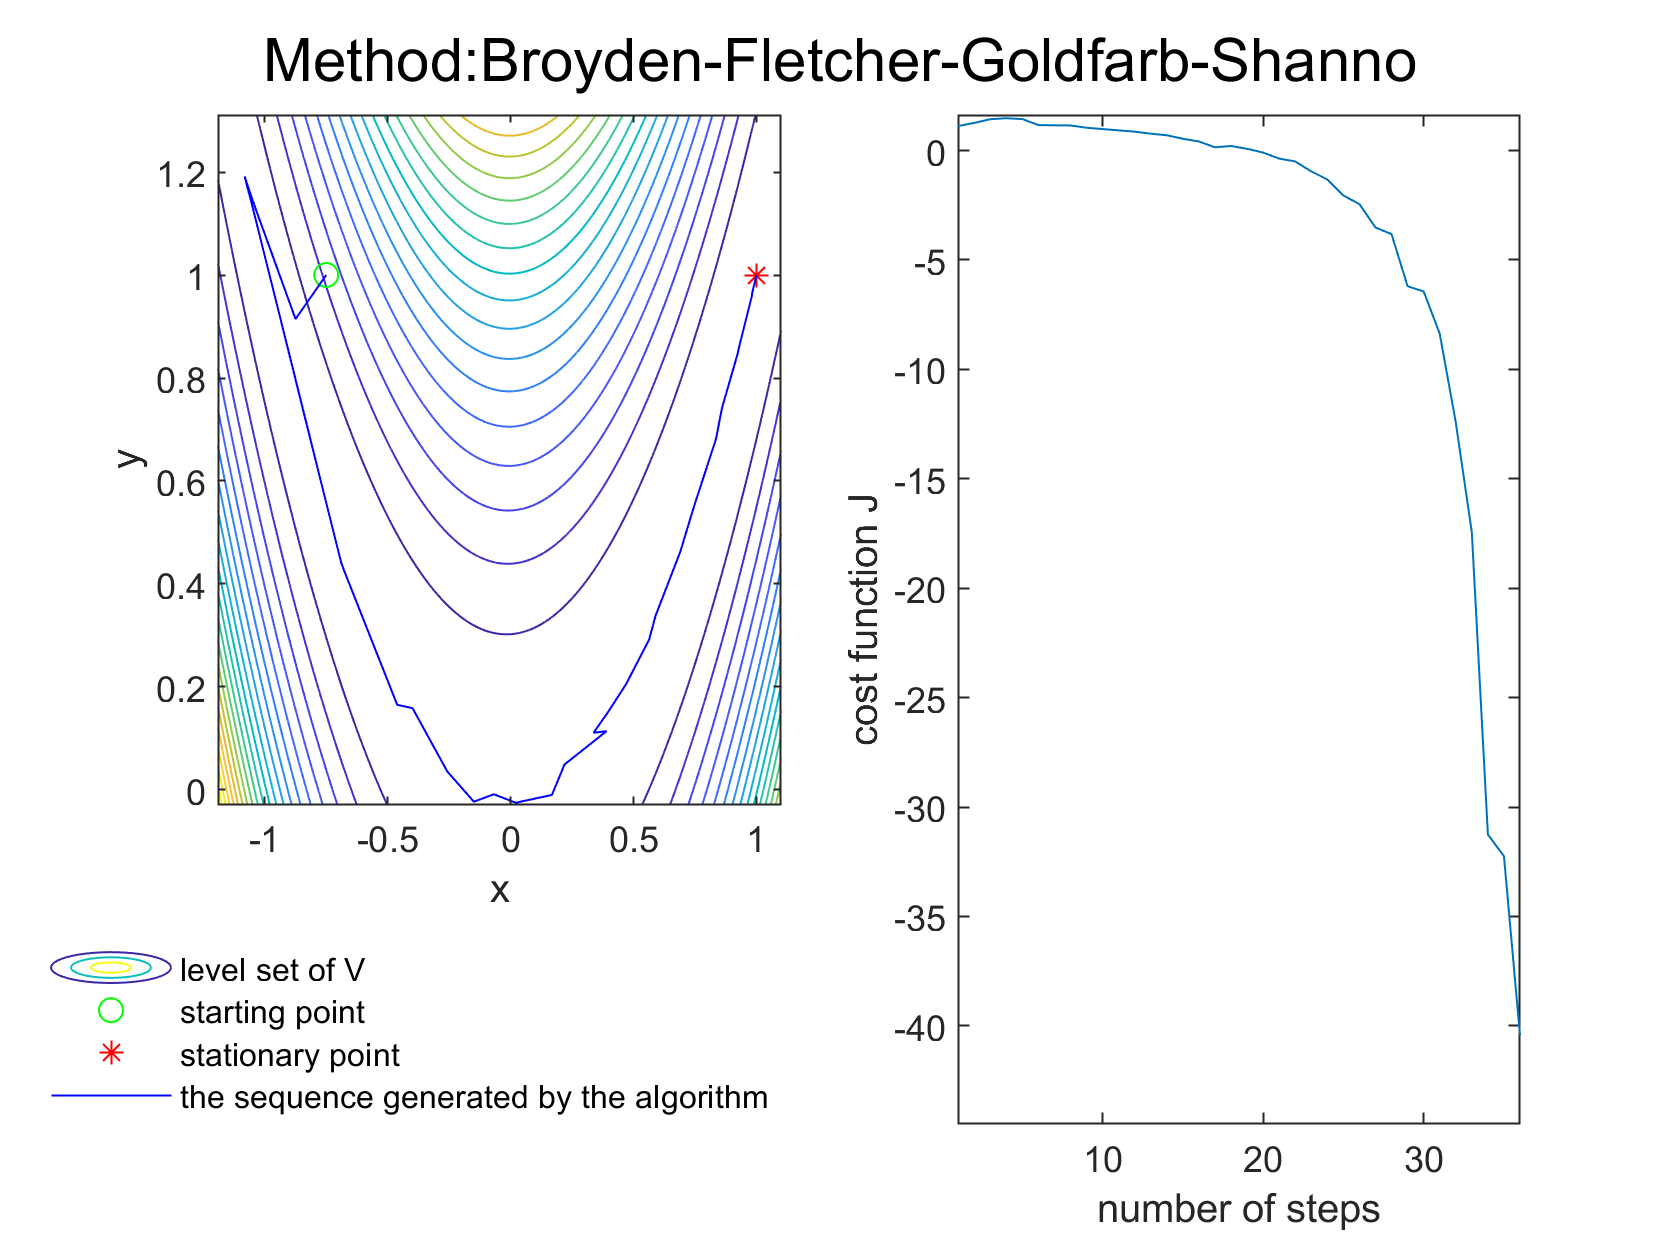

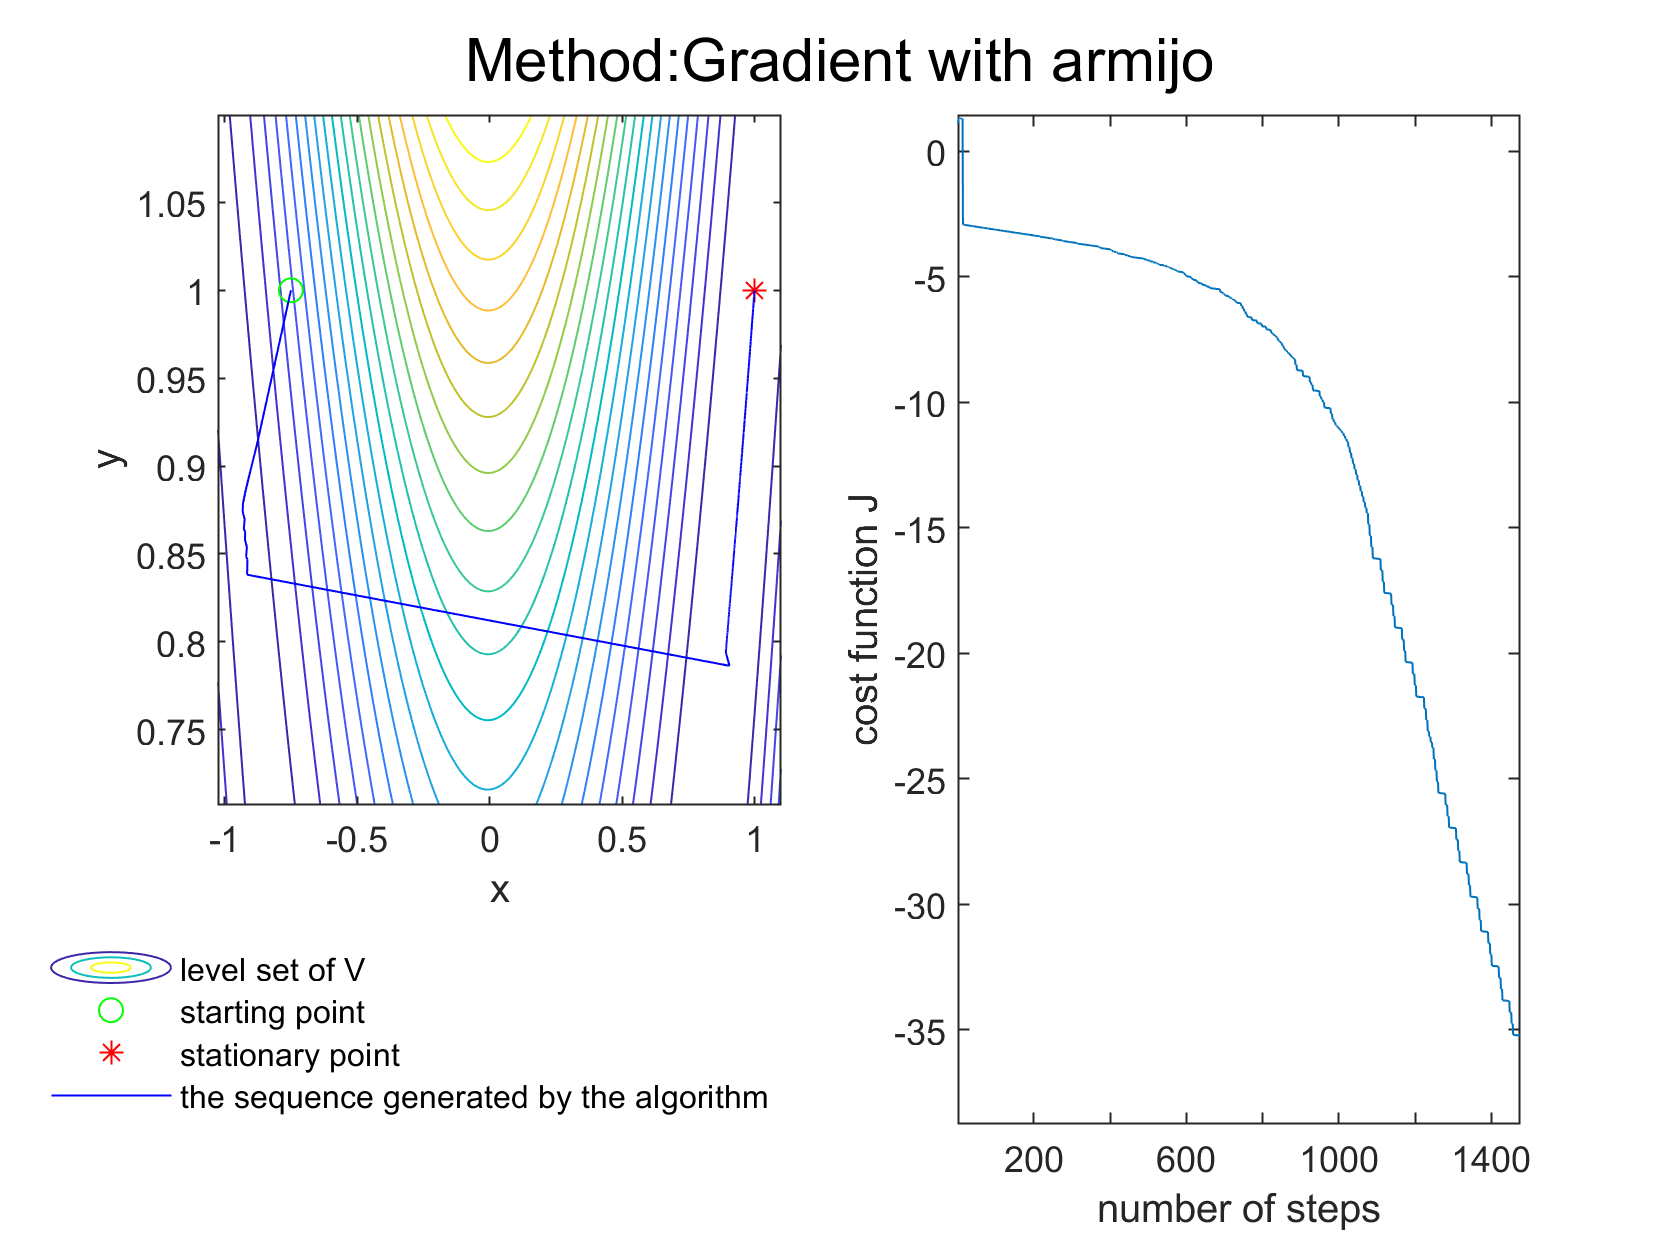

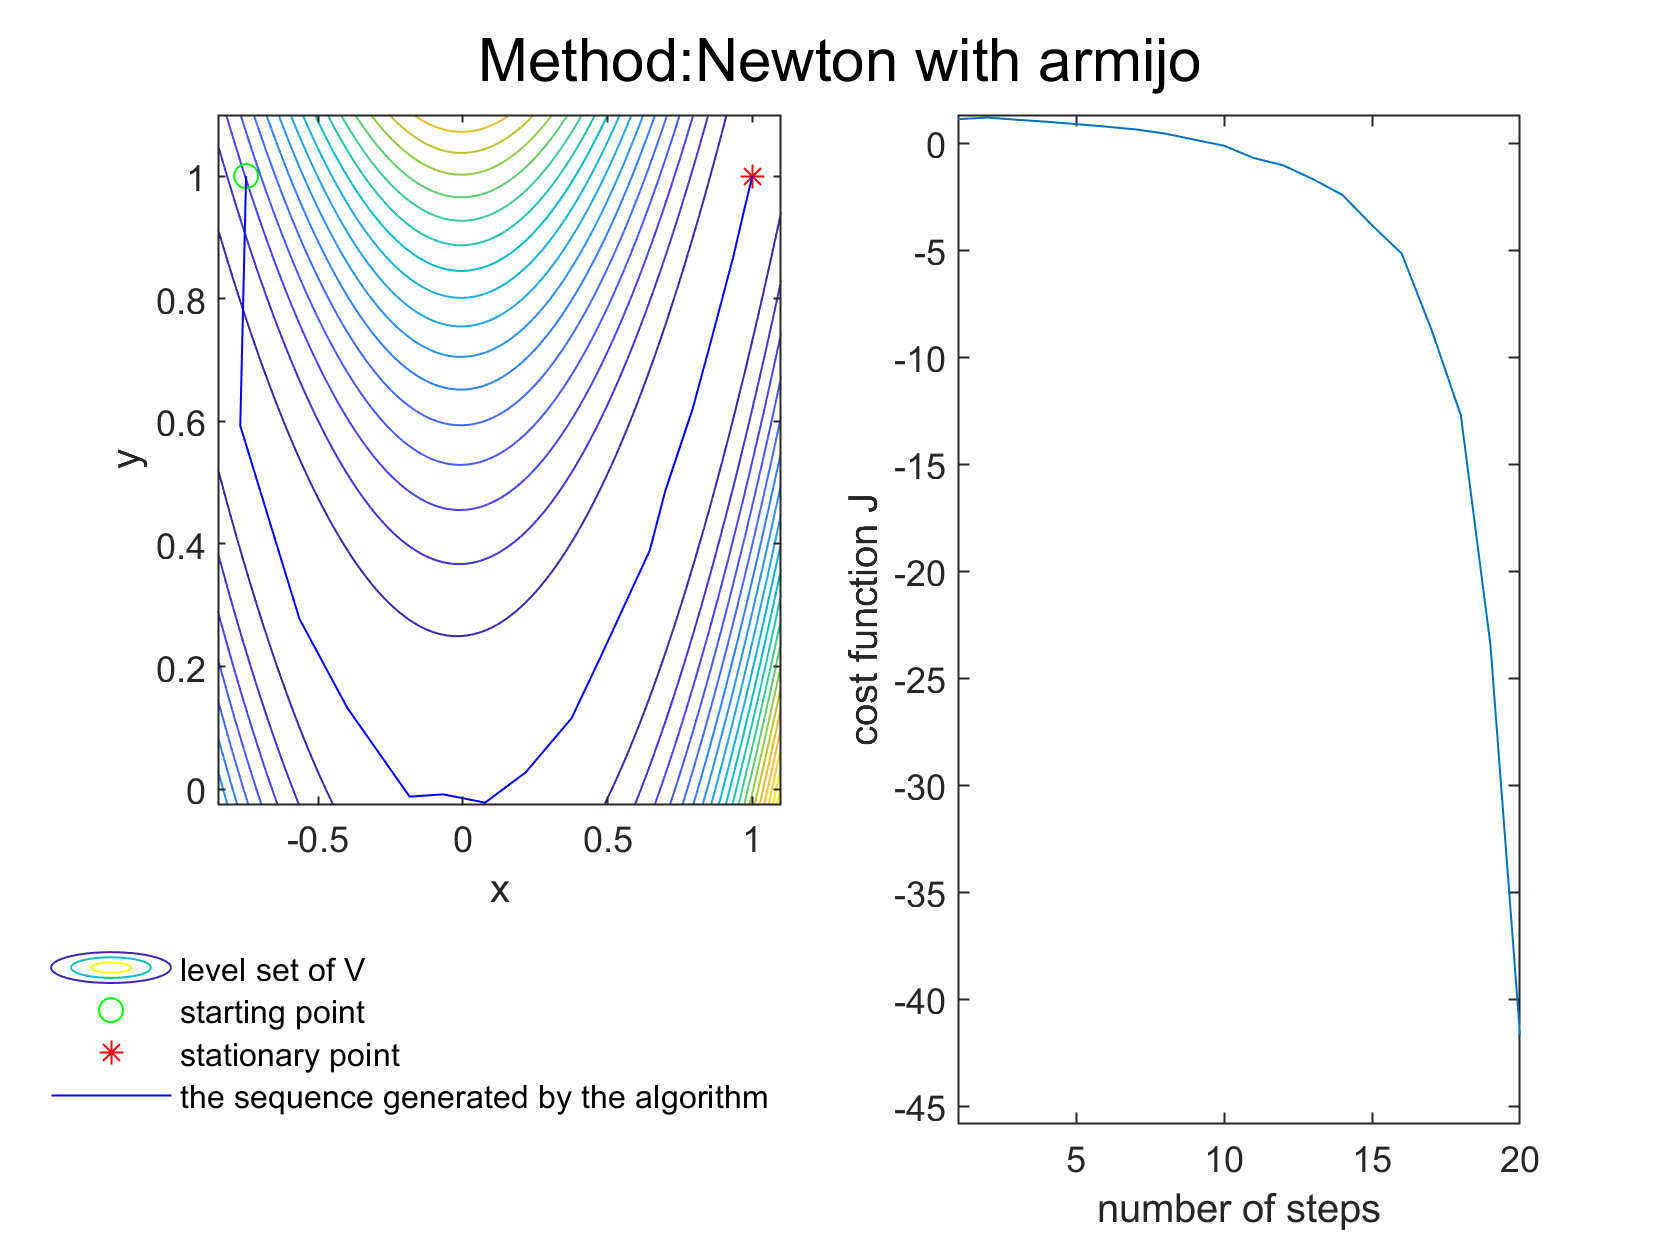

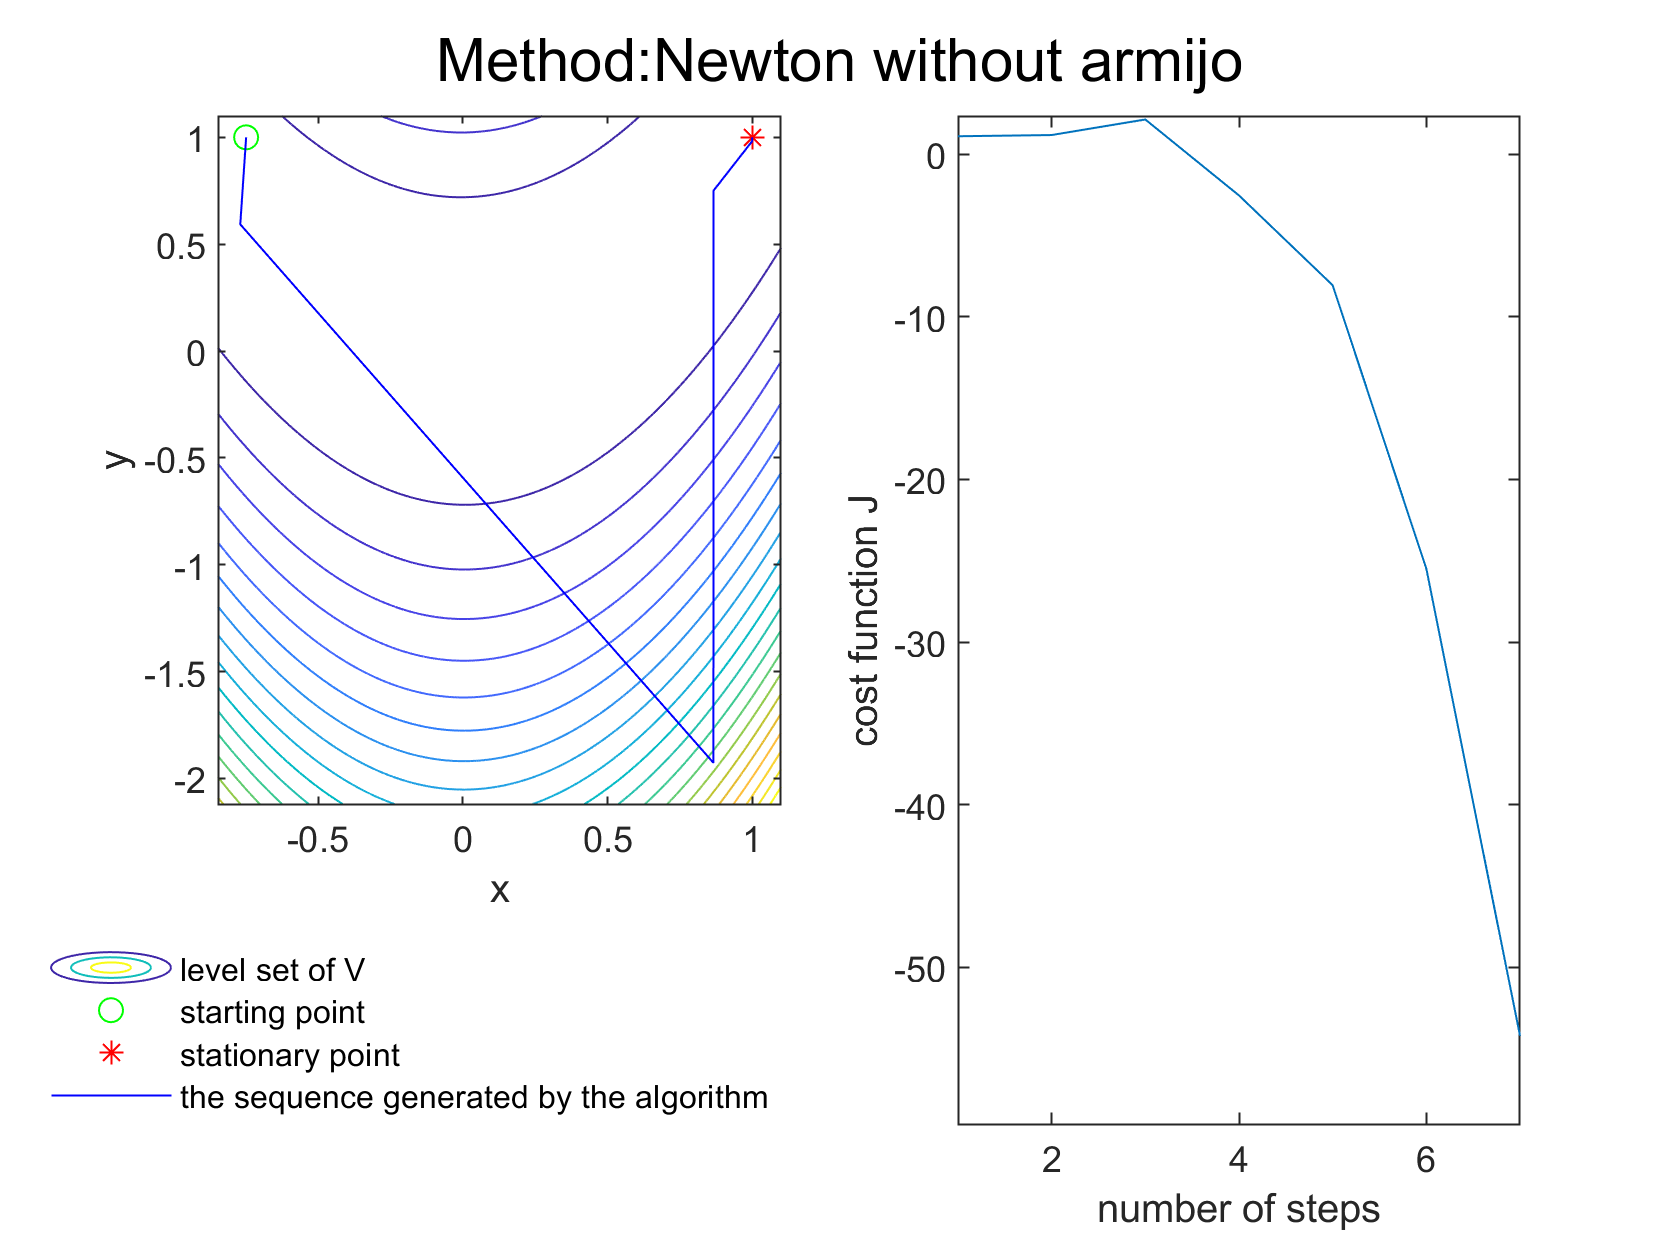

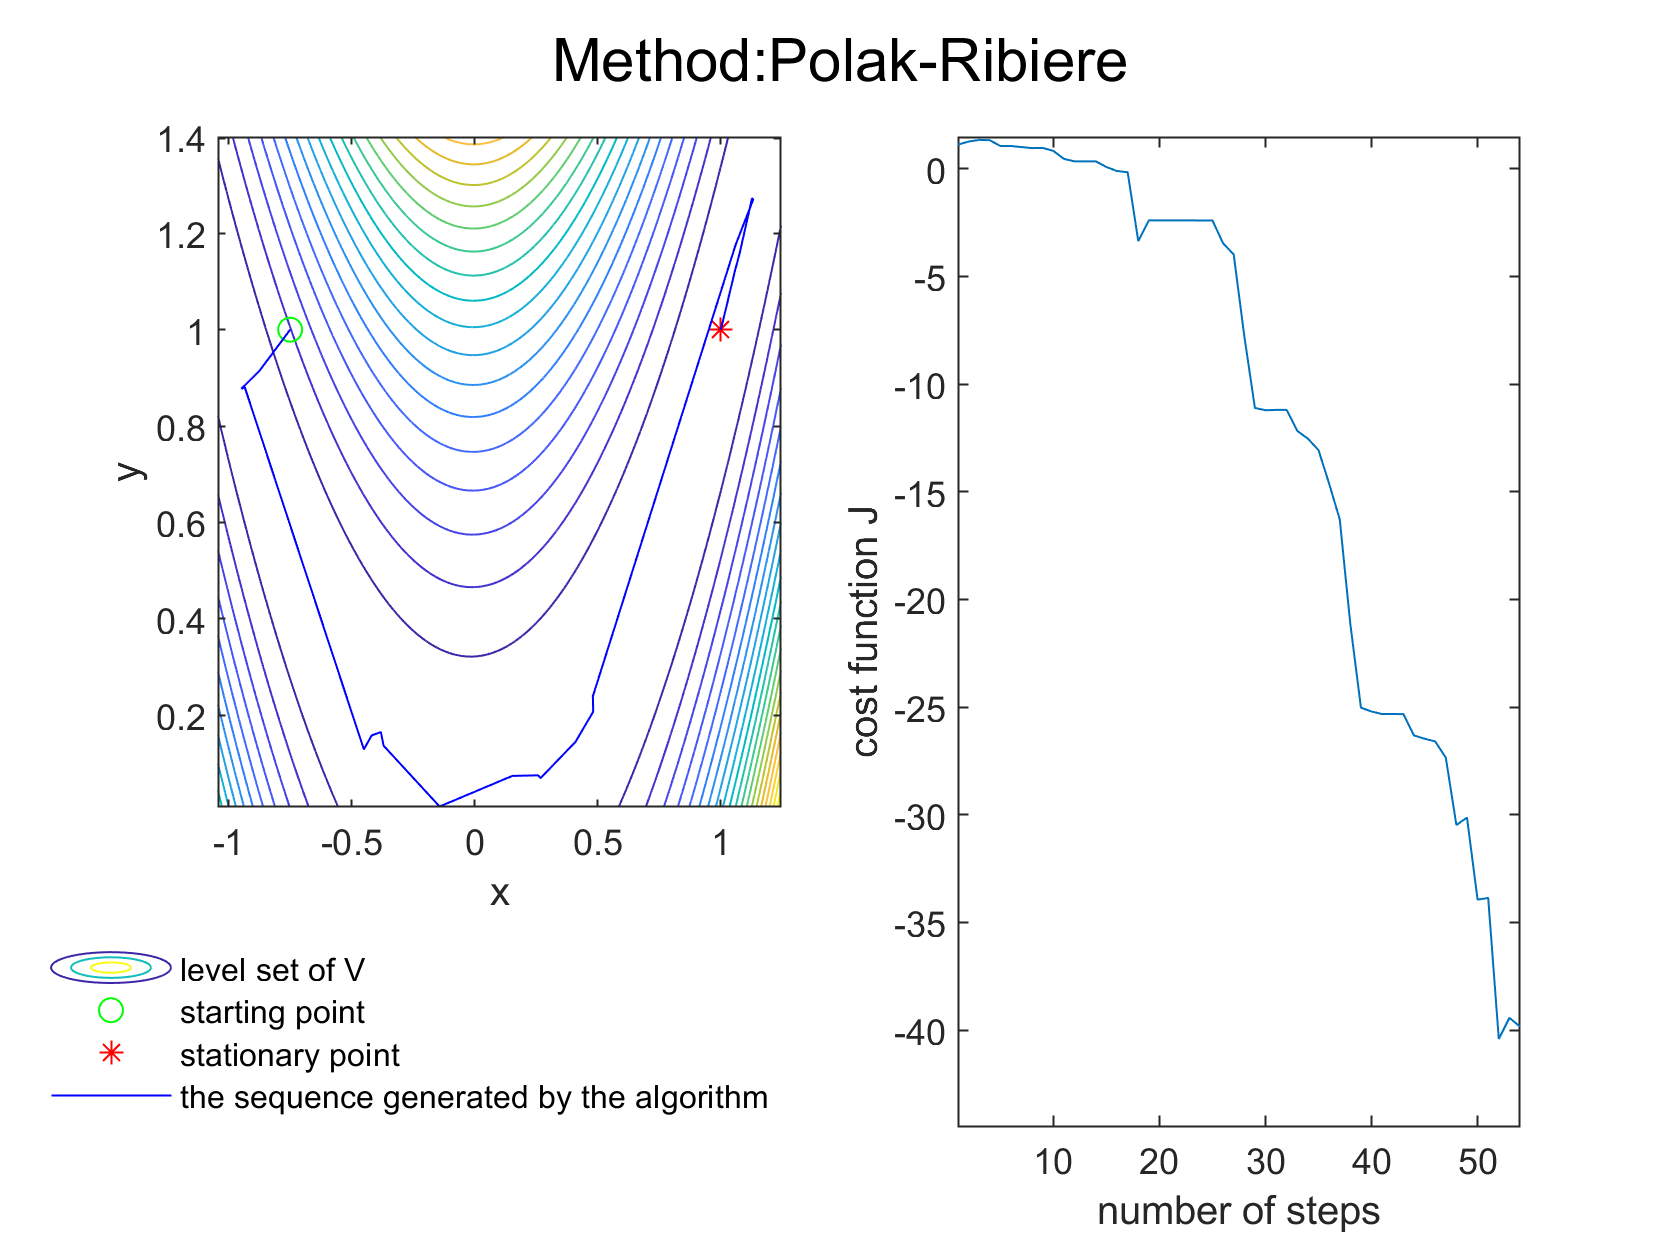

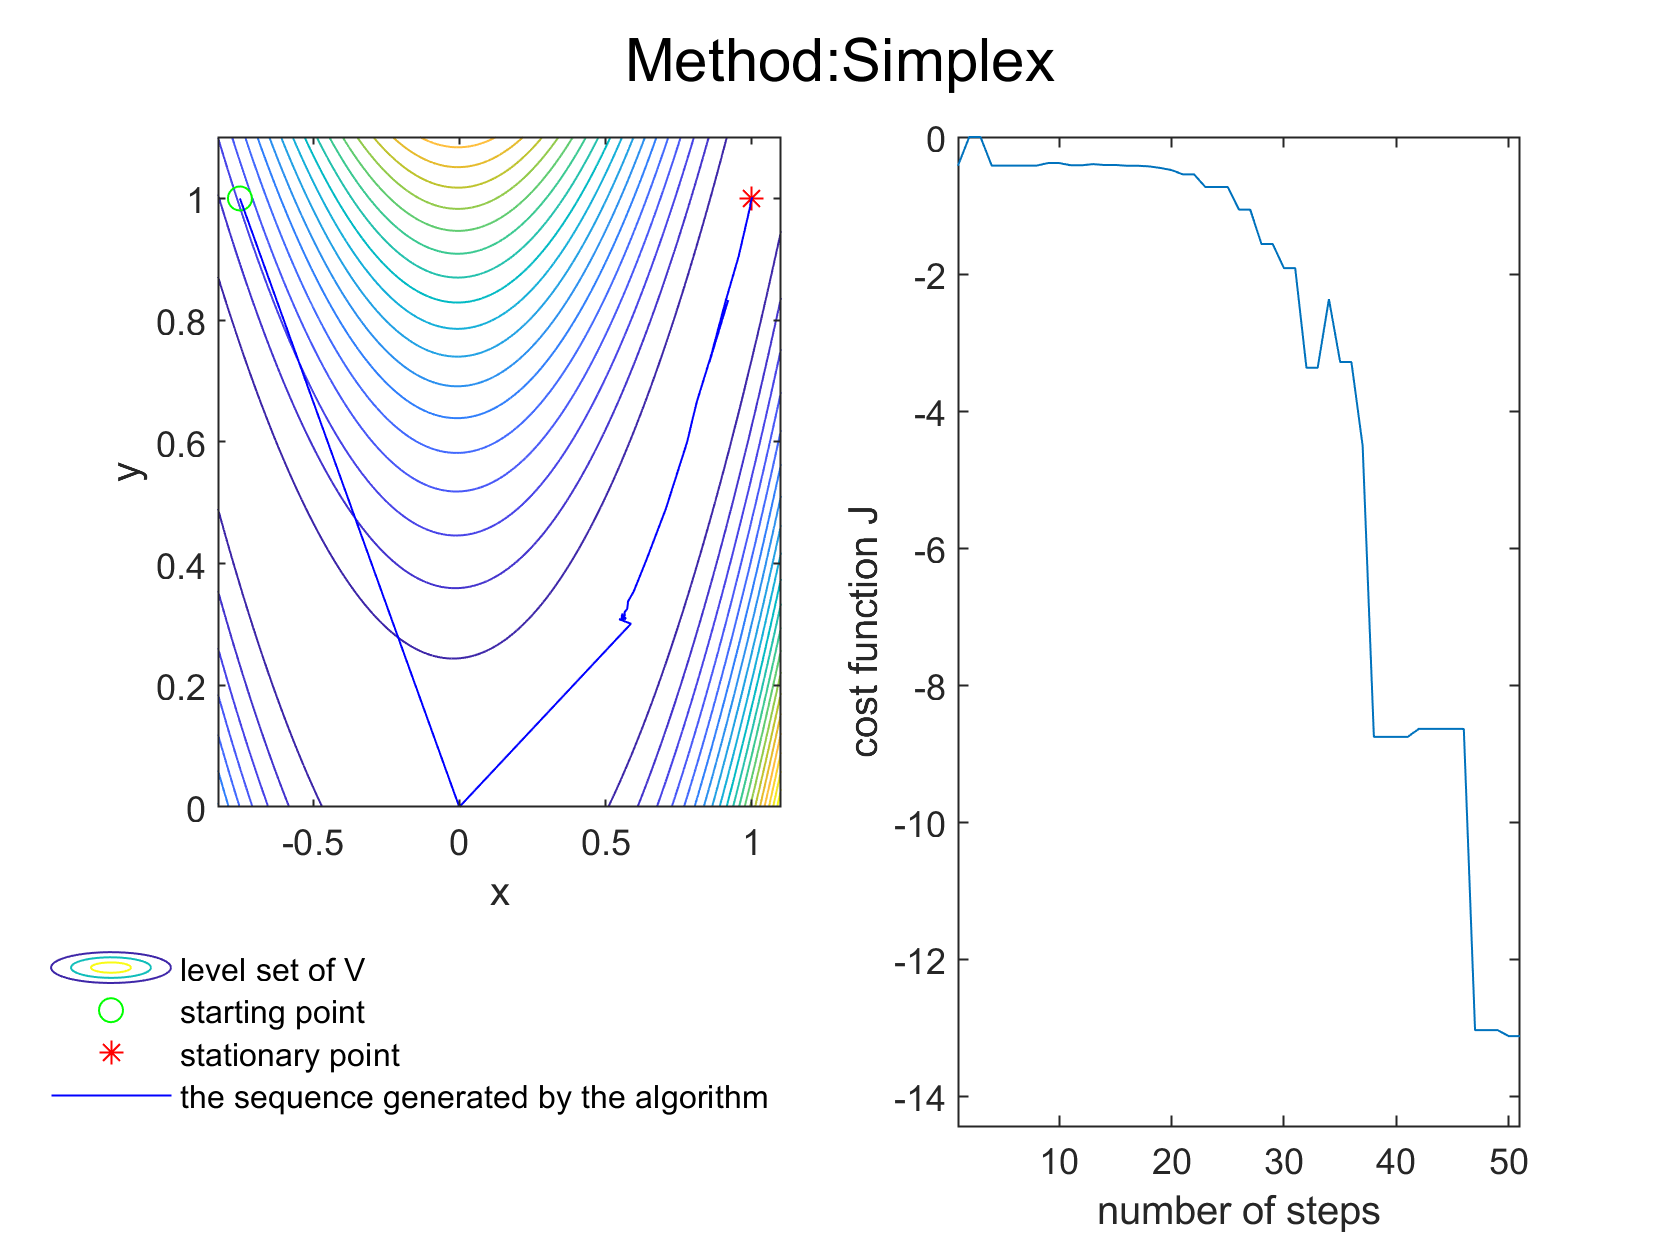

clear;
clc;
data=dir(['*.mat']);
for count=1:length(data)
    load(data(count).name);
    [x,y]=meshgrid([(min(X)-0.1*abs(min(X))):0.001:1.1*max(X)],[(min(Y)-0.1*abs(min(Y))):0.001:1.1*max(Y)]);
    V=v(x,y);
    figure;
    subplot(1,2,1);
    contour(x,y,V,20);
    hold on;
    plot([-3/4],[1],'og',[1],[1],'*r',X,Y,'-b');
    xlabel('x');
    ylabel('y');
    legend('level set of V','starting point','stationary point','the sequence generated by the algorithm',"Location","southoutside");
    legend('boxoff');
    subplot(1,2,2);
    plot(J);
    xlabel('number of steps');
    ylabel('cost function J');
    xlim([size(J)]);
    ylim([1.1*min(J),1.1*max(J)]);
    sgtitle(['Method:',strrep(data(count).name,'.mat','')]);
end

Accordding to the plots, all the sequences generated by the algorithms converge to the stationary point. 

The gradient method with armijo line search has a sublinear speed of convergence.

The Newton method without armijo line search has a superlinear speed of convergence.

The Newton method with armijo line search has a superlinear speed of convergence.

The Polak-Ribiere algorithm with Armijo line search has a superlinear speed of convergence.

The Broyden-Fletcher-Goldfarb-Shanno algorithm with Armijo line search has a superlinear speed of convergence.

The simplex method has a sublinear speed of convergence. [2,3]

## PART II

#### B1) Write the necessary conditions of optimality and find all points satisfying such conditions.

The Lagrangian function of the problem $P_1
$ is

$$$
L\left( x,\lambda \right) =f+\lambda g=-x_1x_2+\lambda \left( x_1+x_2-2 \right) 
$$
$.

The first order necessary condition of optimality can be written as

$$$
\begin{cases}
	\nabla _xL\left( x,\lambda \right) =\left[ \begin{array}{c}
	-x_2+\lambda\\
	-x_1+\lambda\\
\end{array} \right] =0\\
	\nabla _{\lambda}L\left( x,\lambda \right) =g\left( x \right) =x_1+x_2-2=0\\
\end{cases}
$$
$.

Solving the above equations, yielding $$$
x_{1}^{\star}=x_{2}^{\star}=1, \lambda =1
$$
$.

#### B2) Check if the candidate optimal points obtained in B1) are constrained local minimizers or otherwise.

For problem $P_1$, only equality constraints are activated. Solving

$$$
\left[ \frac{\partial g\left( x \right)}{\partial x} \right] s=\left[ \begin{array}{cc}
	1&		1\\
\end{array} \right] s=0
$$
$,

yielding

$$$
s=\left[ \begin{array}{c}
	\alpha\\
	-\alpha\\
\end{array} \right] , \alpha \ne 0
$$
$.

Since


$$$$
s\prime\nabla _{xx}^{2}L\left( x^{\star},\lambda ^{\star} \right) s=\left[ \begin{array}{cc}
	\alpha&		-\alpha\\
\end{array} \right] \left[ \begin{array}{cc}
	0&		-1\\
	-1&		0\\
\end{array} \right] \left[ \begin{array}{c}
	\alpha\\
	-\alpha\\
\end{array} \right] =2\alpha ^2>0
$$
$$


$(x^{\star}_1, x^{\star}_2)$is a strict constrained local minimizer.

#### B3) By solving the equation of the constraint transform the considered constrained optimization problem into an unconstrained problem.

The equality constraint implies that $$$
x_1=2-x_2
$$
$.

Hence, the objective function is modified as

$$$
\tilde{f}=-\left( 2-x_2 \right) x_2=x_{2}^{2}-2x_2
$$
$,

which is an unconstrained problem.

Letting $$$
\nabla \tilde{f}=2x_2-2=0
$$
$, yields that $x_2=1$. Thus, the optimal solution of the orginal problem is $x_{1}^{\star}=x_{2}^{\star}=1$.

#### B4) Construct the exact penalty function G(x) associated to the considered problem. Minimize analytically the function G(x) and show that the unconstrained minimizer of G(x) is a solution of the considered constrained optimization problem.

The exact penalty function G(x) can be written as

$$$
G\left( x \right) =f\left( x \right) +\lambda \left( x \right) g\left( x \right) +\frac{1}{\epsilon}\left\| g\left( x \right) \right\| ^2
$$
$,

where $$$
\lambda \left( x \right) =-\left[ \frac{\partial g}{\partial x}\left( \frac{\partial g}{\partial x} \right) ^T \right] ^{-1}\frac{\partial g}{\partial x}\nabla f
$$
$.

Since $$$
 \frac{\partial g\left( x \right)}{\partial x} =\left[ \begin{array}{cc}
	1&		1\\
\end{array} \right]
$$
$, $$$
\nabla f=\left[ \begin{array}{c}
	-x_2\\
	-x_1\\
\end{array} \right] 
$$
$, 

$\lambda(x)=\frac{1}{2}(x_1+x_2)$.

Thus, 

$$$
G\left( x \right) =-x_1x_2+\frac{1}{2}\left( x_1+x_2 \right) \left( x_1+x_2-2 \right) +\frac{1}{\epsilon}\left( x_1+x_2-2 \right) ^2
$$
$.

Letting $$$
\nabla G\left( x \right) =0
$$
$, implies that

$$$
\begin{cases}
	-x_2+\frac{1}{2}\left( x_1+x_2-2 \right) +\frac{1}{2}\left( x_1+x_2 \right) +\frac{2}{\epsilon}\left( x_1+x_2-2 \right) ^2=0\\
	-x_1+\frac{1}{2}\left( x_1+x_2-2 \right) +\frac{1}{2}\left( x_1+x_2 \right) +\frac{2}{\epsilon}\left( x_1+x_2-2 \right) ^2=0\\
\end{cases}\Rightarrow \left\{ \begin{array}{c}
	\begin{array}{c}
	\begin{array}{l}
	-x_2+1+\left( x_1+x_2-2 \right) +\frac{2}{\epsilon}\left( x_1+x_2-2 \right) ^2=0\\
	-x_1+1+\left( x_1+x_2-2 \right) +\frac{2}{\epsilon}\left( x_1+x_2-2 \right) ^2=0\\
\end{array}\\
\end{array}\\
\end{array} \right. 
$$
$.

Adding the two equations above

$$$
-\left( x_1+x_2-2 \right) +\left( \frac{4}{\epsilon}+2 \right) \left( x_1+x_2-2 \right) =0
$$
$,

which is equivalant to 

$$$
\left( \frac{4}{\epsilon}+1 \right) \left( x_1+x_2-2 \right) =0
$$
$.

Since $\epsilon>0$, the following equation must be satisfied

$x_1+x_2-2  =0$.

Substituing $x_1+x_2-2=0$ back into $\nabla G(x)=0$, one can get

$$$
\begin{cases}
	-x_1+1=0\\
	-x_2+1=0\\
\end{cases}
$$
$,

which implies that the unconstrained minimizer of $G(x)$ is $x_{1}^{\star}=x_{2}^{\star}=1$.

Thus, the unconstrained minimizer of $G(x)$ is a solution of the considered constrained optimization problem.

#### B5) Construct the exact augmented Lagrangian function $S(x,\lambda)$ associated to the considered problem. Minimize analytically the function $S(x,\lambda)$ and show that the unconstrained minimizer of $S(x,\lambda)$ yields a solution of the considered constrained optimization problem and the corresponding optimal multiplier.

The exact augmented Lagrangian function $S(x,\lambda)$ can be written as

$$$
S\left( x,\lambda \right) =f\left( x \right) +\lambda g\left( x \right) +\frac{1}{\epsilon}\left\| g\left( x \right) \right\| ^2+\eta \left\| \frac{\partial g\left( x \right)}{\partial x}\nabla _xL\left( x,\lambda \right) \right\| ^2
$$
$.

Since $$$
 \frac{\partial g\left( x \right)}{\partial x} =\left[ \begin{array}{cc}
	1&		1\\
\end{array} \right]
$$
$, $$$
\nabla f=\left[ \begin{array}{c}
	-x_2\\
	-x_1\\
\end{array} \right] 
$$
$，

$$$
S\left( x,\lambda \right) =-x_1x_2+\lambda \left( x_1+x_2-2 \right) +\frac{1}{\epsilon}\left( x_1+x_2-2 \right) ^2+\eta \left( x_1+x_2-2\lambda \right) ^2
$$
$.

Letting $$$
\nabla _xS\left( x,\lambda \right) =0
$$
$,

$$$
\begin{cases}
	-x_2+\lambda +\frac{2}{\epsilon}\left( x_1+x_2-2 \right) +2\eta \left( x_1+x_2-2\lambda \right) =0\\
	-x_1+\lambda +\frac{2}{\epsilon}\left( x_1+x_2-2 \right) +2\eta \left( x_1+x_2-2\lambda \right) =0\\
\end{cases}
$$
$.

By adding the two equations above, one can get

$$$
\frac{4}{\epsilon}\left( x_1+x_2-2 \right) +\left( 4\eta -1 \right) \left( x_1+x_2-2\lambda \right) =0
$$
$.

Letting $$$
\nabla _\lambda S\left( x,\lambda \right) =0
$$
$,

$$$
\left( x_1+x_2-2 \right) -4\eta \left( x_1+x_2-2\lambda \right) =0
$$
$.

By adding these two equations, one can get

$$$
\left( \frac{4}{\epsilon}+1 \right) \left( x_1+x_2-2 \right) -\left( x_1+x_2-2\lambda \right) =0
$$
$,

which is equivalant to 

$$$
\frac{4}{\epsilon}\left( x_1+x_2-2 \right) +\left( 2\lambda -2 \right) =0
$$
$,

implying

$$$
\begin{cases}
	x_1+x_2-2=0\\
	2\lambda -2=0\\
\end{cases}
$$
$.

Substituing these equations back into $$$
\nabla _\lambda S\left( x,\lambda \right) =0
$$
$, one can claim the unconstrained minimizer of $S(x,\lambda)$ is $x_{1}^{\star}=x_{2}^{\star}=1$, with the optimal multiplier $\lambda^\star=1$, which are also the solution of the considered optimization problem and the corresponding optimal multiplier.

#### Reference

[1] Wikipedia. *Nelder–Mead method. *Available from: [https://en.wikipedia.org/wiki/Nelder%E2%80%93Mead_method](https://en.wikipedia.org/wiki/Nelder%E2%80%93Mead_method) [Accessed 4th January 2021].

[2] Wikipedia. *Rate of convergence. *Available from: [https://en.wikipedia.org/wiki/Rate_of_convergence#Examples](https://en.wikipedia.org/wiki/Rate_of_convergence#Examples) [Accessed 4th January 2021].

[3] Wikipedia. *Semi-log plot. *Available from: [https://en.wikipedia.org/wiki/Semi-log_plot](https://en.wikipedia.org/wiki/Semi-log_plot) [Accessed 4th January 2021].

#### Appendix

Matlab functions used in algorithm implementations

All the codes are available [here](https://github.com/LHYi/OPT_CW).